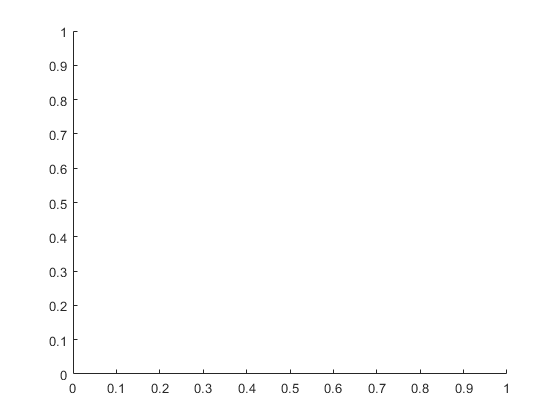

%AQUÍ SE IMPLEMENTA UN RUIDO EN LA MEDICIÓN DEL CAMPO ESCALAR
%O UN CIERTO ERROR EN LA FORMACIÓN DE LOS ROBOTS (LAS DOS A LA VEZ NO SE
%COMENTA EN LOS PAPERS)


clear
close all
hold off


%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
delta=0.1;
%HACER ANIMACIÓN DE TODO ESTO

%Vamos a representar cómo se mueve el centro de la formación

N=8; %Número de robots
iteration=500; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[100,1,1;1,1,0;1,0,10]; %Matriz
c0_initial=[15;15;8]; %Posición del centro inicial (initial guess)
r0=[0 0 0]'; %Centro de contaminación (hay que saberlo, está dado por la función)
w0=1; %Movimiento circular de un radián por segundo
a=0.001;

colors=["ob","ok","or","oy","og","om","oc","ob","ok","om","or"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
mod_rc=mod_r_c(1);
pos_rob=zeros(3,N+3,iteration);
i=1;
simulation=100; %número de simulaciones
mod_rc_simulation=zeros(iteration,simulation);

%Se aplica el método del Hessiano
for k=1:simulation
    i = 1;
    c0 = c0_initial;
    while mod_rc>0.001
        if i==iteration
            break
        end
        grad_sum=0;
        K=0;
        i=i+1;
        for j=1:N+2
            %Determinación del ángulo azimutal
            if j<=N
                phi=w0*t(i)+2*pi()*j/N;
            else
                phi=0;
            end
            %Determinación del ángulo polar, ESTO HAY QUE CAMBIAR
            if j<=N
                if rem(j,2)==0
                    theta=pi-0.955316618;
                else
                    theta=0.955316618;
                end
            else
                %Ángulo polar para los dos últimos robots
                theta = pi * (j - N - 1);
            end
            %Posición del robot individual (esfera)
            
            delta_i=0;
            %delta_i=normrnd(0,delta^2,[3 1]);
            r_i=c0+D*[sin(theta)*cos(phi);sin(theta)*sin(phi);cos(theta)]+delta_i;
            pos_rob(:,j,i)=r_i;
            %Suma para la K
            v_i=normrnd(0,v^2);
            v_c=normrnd(0,v^2);
            K=K+(100*exp(-r_i'*S*r_i)+v_i-100*exp(-c0'*S*c0))*(r_i-c0)*(r_i-c0)';
            if j<N+1
                %Suma para el gradiente (se tiene en cuenta cada
                %robot)
                grad_sum=grad_sum+100*exp(-r_i'*S*r_i)*(r_i-c0);
            end
        end
        %Sumar al vector de posiciones de robot la posición del robot en el
        %centro de la formación
        pos_rob(:,N+3,i)=c0;
        %Aproximación del gradiente en el centro
        grad_centr=3/(N*D^2)*grad_sum;
        %Aproximación de K en el centro
        K_centr=18/(N*D^4)*K;
        %Aproximación del Hessiano, solución de la ecuación general:
        H12=K_centr(2,1);
        H13=K_centr(1,3)/2;
        H23=K_centr(2,3)/2;
        A=[3/2 1/2 1;1/2 3/2 1;1 1 1+18/N];
        b=[K_centr(1,1);K_centr(2,2);K_centr(3,3)];
        vec_x=linsolve(A,b);
        H11=vec_x(1,1);
        H22=vec_x(2,1);
        H33=vec_x(3,1);
        H=[H11 H12 H13;H12 H22 H23;H13 H23 H33];
        %El Hessiano debe ser positiva definida, si alguno de los
        %autovalores es negativo, no se cumple, por ello se hace la
        %siguiente aproximación, es más costoso porque requiere calcular
        %los autovalores de la matriz
        if any(eig(H) <= 0)
            H = -1 *  eye(3);
        end
        %Para que no sea tan costoso, se hace esta comparación:
        %I = eye(3); % Matriz identidad en 3 dimensiones
        %if H > -a*I
            %H = -I;
        %end

        H_inv=inv(H);
        %Aplicación de la aproximación por el Hessiano, siguiente centro
        c(:,i)=c0-step_size*H_inv*grad_centr;
        %c(:,i)=c0+step_size*grad_centr;
        c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0);
        mod_rc=mod_r_c(i);
    end
    mod_rc_simulation(:,k)=mod_r_c;
end

%Representación de la media y la desviación estándar
for h=1:iteration
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end

Index in position 1 exceeds array bounds (must not exceed 1).

errorbar(1:100,media(1:100),desv_std(1:100),'.')

%Representación del centro
%plot3(c(1,:),c(2,:),c(3,:),'.r')

%Representación de los robots
%for g=1:N+3
    %for z=2:iteration
        %plot3(pos_rob(1,g,z),pos_rob(2,g,z),pos_rob(3,g,z),colors(g))
        %hold on
    %end
%end
%hold off
%plot(1:length(mod_r_c),mod_r_c,".")
%xlabel("Iteraciones")
%ylabel("Módulo de la diferencia")
%grid on

%error final para cada step-size
%error=norm(c(:,length(mod_r_c))-r0)
%c0
%for p=1:N+3
    %plot3(pos_rob(1,p,length(mod_r_c)),pos_rob(2,p,length(mod_r_c)),pos_rob(3,p,length(mod_r_c)),colors(p))
    %hold on
%end
